# TRABALHO CONTROLE DE UM MOTOR PMSM

## Ponto de operação

% PARAMETROS DO MOTOR
R = 0.16;
L = 1.3e-4;
N = 10;
J = 1.8e-4;
b = 1e-5;
lamb = 0.06;
Kt = 0.095;

% CONDIÇOES DE OPERAÇAO
w = 150;
id = 0;

% OBTER iq
%J*(w') + b*w = Kt*(iq), logo:
iq = b*w/Kt;

% OBTER Vd
%Vd = L*(d(id)/dt) + R*(id) - N*L*W*(iq), logo:
Vd = -N*L*w*(iq);

% OBTER Vq
%Vq = L*(d(iq)/dt) + R*iq + N*L*W*id + ((sqtr(6)/2)*N*w*lamb), logo:
Vq = R*(iq) + ((sqrt(6)/2)*N*w*lamb);


## Linearização

%  x' = f(x,u) -> x' = Ax + BU

% d/dt[id; iq; w] = [(1/L)*(-R*(id)+N*L*w*(iq)+Vd);
%                    (1/L)*(-R*(iq)+N*L*w*(id)-(sqrt(6)/2)*N*lamb*w+Vq);
%                    (1/J)*(-b*w+(kt)*(iq))]

% A = derivada parcial de cada estado
% B = derivada parcial de cada entrada


A = [(-R/L)    (N*w)                    (N*iq);
    -N*w       (-R/L)     ((-N*id)-(sqrt(6)/2)*N*lamb*1/L);
      0        (Kt/J)                   (-b/J)];

 
B = [(1/L)   0;
       0   (1/L);
       0     0];


## Analise do ganho no sistema

% OBTENCAO DAS FUNCOES DE TRANSFERENCIA PARA ANALISE PURAMENTE DE UM GANHO

% G(s) = (C*[S*I-A]^(-1))*B + D

%1º forma:
%syms s 
%G = inv(s*I-A)*B

%2º forma:
% [n,d] = ss2tf(A,B,I,B*0,1ou2)
C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


D = B*0

D =      0     0
     0     0
     0     0


[n1,d1] = ss2tf(A,B,C,D,1)

n1 = 	1.0e+10 *

         0    0.0000    0.0009    2.2949
         0         0   -0.0012   -0.0001
         0         0         0   -0.6090


d1 = 	1.0e+09 *

    0.0000    0.0000    0.0067    3.6722


[n2,d2] = ss2tf(A,B,C,D,2)

n2 = 	1.0e+09 *

         0         0    0.0115    0.0013
         0    0.0000    0.0095    0.0005
         0         0    0.0041    4.9967


d2 = 	1.0e+09 *

    0.0000    0.0000    0.0067    3.6722



% Funções de transferencia
H11 = tf(n1(1,:),d1);
H21 = tf(n1(2,:),d1);
H31 = tf(n1(3,:),d1);
H12 = tf(n2(1,:),d2);
H22 = tf(n2(2,:),d2);
H32 = tf(n2(3,:),d2);


% Determinação de Ks para obter kp e ki
% kp = k*k1
% ki = k*k2

% -------------------------------------------------------------
k1 = 1;
k2 = 1.5;

numM = [k1 k2];
denM = [1 0];
M = tf(numM,denM) 

M =
 
  s + 1.5
  -------
     s
 
Continuous-time transfer function.




G1 = M*H11  % Crime, mudança da planta com K como controlador

G1 =
 
  7692 s^3 + 9.479e06 s^2 + 2.296e10 s + 3.442e10
  -----------------------------------------------
    s^4 + 2462 s^3 + 6.748e06 s^2 + 3.672e09 s
 
Continuous-time transfer function.



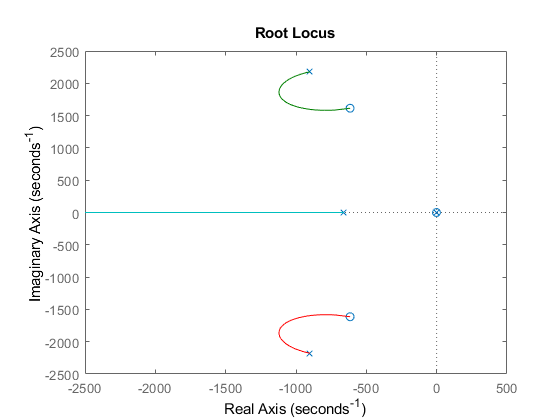

rlocus(G1)


k = 0.278 % Obtido pelo rotlocus, overshoot = 0

k = 0.2780


kp = k * k1;
ki = k * k2;

numD = [kp ki];
denD = [1 0];
D1=tf(numD,denD) % FT do controlador, sem o crime

D1 =
 
  0.278 s + 0.417
  ---------------
         s
 
Continuous-time transfer function.




% -------------------------------------------------------------
k12 = 2;
k22 = 1;

numM2 = [k12 k22];
denM2 = [1 0];
M2 = tf(numM2,denM2)

M2 =
 
  2 s + 1
  -------
     s
 
Continuous-time transfer function.




G2 = M2*H22 % Crime, mudança da planta com K como controlador

G2 =
 
  1.538e04 s^3 + 1.894e07 s^2 + 1.052e07 s + 5.26e05
  --------------------------------------------------
      s^4 + 2462 s^3 + 6.748e06 s^2 + 3.672e09 s
 
Continuous-time transfer function.



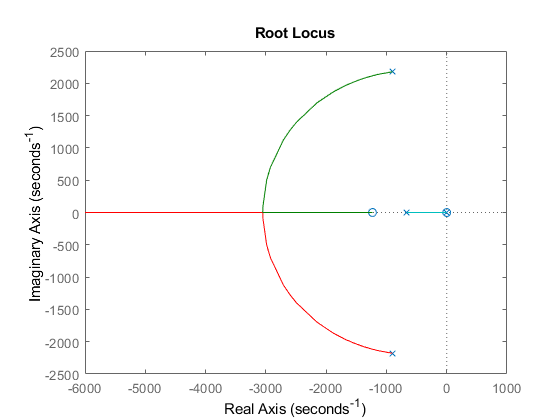

rlocus(G2)


k2 = 0.25 % Obtido pelo rotlocus, overshoot = 0

k2 = 0.2500


kp2 = k2 * k12;
ki2 = k2 * k22;

numD2 = [kp2 ki2];
denD2 = [1 0];
D2=tf(numD2,denD2); % FT do controlador, sem o crime

% -------------------------------------------------------------
% J*wponto + b*w = Tal
% J*S*W(S) + b*W(S) = T(S)
% W(S)/T(S) = 1/(J*S+b)

numH3 = [0 1];
denH3 = [J b];
H3 = tf(numH3,denH3)

H3 =
 
          1
  -----------------
  0.00018 s + 1e-05
 
Continuous-time transfer function.




% -------------------------------------------------------------
k13 = 1;
k23 = 2;

numM3 = [k13 k23];
denM3 = [1 0];
M3 = tf(numM3,denM3) 

M3 =
 
  s + 2
  -----
    s
 
Continuous-time transfer function.



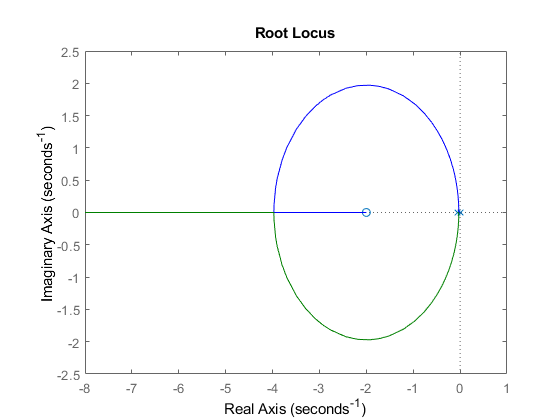


G3 = H3*M3;  % Crime, mudança da planta com K como controlador
rlocus(G3)


k3=0.00135  % Obtido pelo rotlocus, overshoot = 0

k3 = 0.0014


kp3 = k3 * k13;
ki3 = k3 * k23;

numD3 = [kp3 ki3];
denD3 = [1 0];
D3=tf(numD3,denD3) % FT do controlador, sem o crime

D3 =
 
  0.00135 s + 0.0027
  ------------------
          s
 
Continuous-time transfer function.



## Obtenção de Novas matrizes com aumento de espaço

% Matriz nova de A
z = zeros(6,3);
ident = eye(3); 
An = cat(1,A,ident);
An = cat(2,An,z)

An = 	1.0e+03 *

   -1.2308    1.5000    0.0002         0         0         0
   -1.5000   -1.2308   -5.6527         0         0         0
         0    0.5278   -0.0001         0         0         0
    0.0010         0         0         0         0         0
         0    0.0010         0         0         0         0
         0         0    0.0010         0         0         0



% Matriz nova de B
Bn = [B;0 0;0 0; 0 0]

Bn = 	1.0e+03 *

    7.6923         0
         0    7.6923
         0         0
         0         0
         0         0
         0         0



Cn = eye(6)

Cn =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


Dn = Bn*0

Dn =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0


## LQR

% Pesos dado aos espaços individuais 
pid1 = 1;    % Espaço id
piq2 = 1;    % Espaço iq
pw3 = 2000;  % Espaço w
pidi4 = 1;   % Espaço id integral
piqi5 = 1;   % Espaço iq integral
pwi6 = 1;    % Espaço w  integral

% Penalização mediante aos limites do modelo
% wmáx = 250 rad/s
% (id²+iq²)^(1/2) = 3A
% (vd²+vq²)^(1/2) = 50V

q11 = pid1*1/(3^2);
q22 = piq2*1/(3^2);
q33 = pw3*1/(250^2);
q44 = pidi4*1/(3*0.01)^2;
q55 = piqi5*1/(3*0.01)^2;
q66 = pwi6*1/(250*0.01)^2;

% Pesos dado as entradas de controle 
r11 = 1/(50^2);  % Entrada Vd
r22 = 15/(50^2); % Entrada Vq

% -------------------------------------------------------------
Q = diag([q11 q22 q33 q44 q55 q66])

Q = 	1.0e+03 *

    0.0001         0         0         0         0         0
         0    0.0001         0         0         0         0
         0         0    0.0000         0         0         0
         0         0         0    1.1111         0         0
         0         0         0         0    1.1111         0
         0         0         0         0         0    0.0002


Rlqr = diag([r11 r22])

Rlqr =     0.0004         0
         0    0.0060



% Termo de acoplamento entre estados e entradas
Nn = [0 0;
      0 0;
      0 0;
      0 0;
      0 0;
      0 0]

Nn =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0



[K,S,CLP] = lqr(An, Bn, Q, Rlqr, Nn);


Kdid = K(1,1);   % Ganho referente a id para  Vd
Kdiq = K(1,2);   % Ganho referente a iq para  Vd
Kdw = K(1,3);    % Ganho referente a w para  Vd
Kdidi = K(1,4);  % Ganho referente a id integral para  Vd 
Kdiqi = K(1,5);  % Ganho referente a id integral para  Vd
Kdwi = K(1,6);   % Ganho referente a id integral para  Vd

Kqid = K(2,1);   % Ganho referente a id para  Vq
Kqiq = K(2,2);   % Ganho referente a iq para  Vq
Kqw = K(2,3);    % Ganho referente a w para  Vq
Kqidi = K(2,4);  % Ganho referente a id integral para  Vq 
Kqiqi = K(2,5);  % Ganho referente a id integral para  Vq
Kqwi = K(2,6);   % Ganho referente a id integral para  Vq



## Filtro de Kalman

tempo=linspace(0,0.1,101)'; % Amostragem de 1 kHz

sigmaDm = 5; % Intensidade do ruído da saída medida  id
sigmaQm = 5; % Intensidade do ruído da saída medida iq
sigmaw = 90; % Intensidade do ruído da saída medida w

sigmaDs = 5; % Intensidade do ruído na entrada do sistema
sigmaQs = 5; % Intensidade do ruído na entrada do sistema

% Qk = diag([sigmaDs^2 sigmaQs^2]);          % Matriz de covariância do ruído de entrada do sistema
% Rk = diag([sigmaDm^2 sigmaQm^2 sigmaw^2]); % Matriz de covariância do ruído da saída medida

Qk = [0.1   0   0;
       0   0.5  0;
       0    0   1]

Qk =     0.1000         0         0
         0    0.5000         0
         0         0    1.0000



Rk = [1   0   0;
      0   1   0;
      0   0   5]

Rk =      1     0     0
     0     1     0
     0     0     5


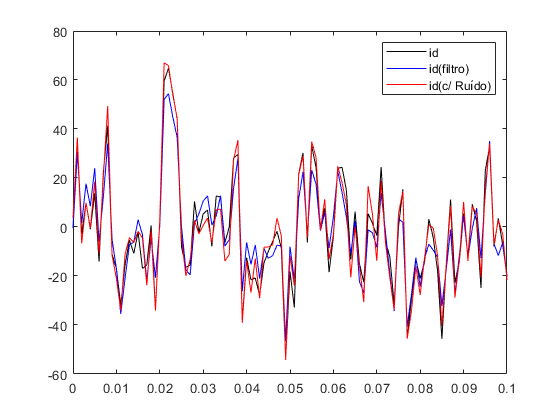



wk = [sigmaDs*randn(numel(tempo),1)    sigmaQs*randn(numel(tempo),1)]; % Vetores de ruído de entrada do sistema
vk = [sigmaDm*randn(numel(tempo),1)    sigmaQm*randn(numel(tempo),1)      sigmaw* randn(numel(tempo),1)]; % Vetores de ruído da saída medida
uk = [1*sin(500*tempo)                 tempo*0+10]; % Entrada do sistema

sysc=ss(A,B,C,0);
sys = c2d(sysc,tempo(2),'zoh'); % Discretização

Ak = sys.A;
Bk = sys.B;
Ck = sys.C;

y = lsim(sys,uk+wk); % Saída do sistema simulado com entrada mais o ruído do processo
yruido = y + vk; 


% Implementação do filtro

Pk = Bk*(Bk')*Qk; % Covariância
x = zeros(3,1); 
yestimativa = zeros(3,length(tempo)); 

for i=1:length(tempo) %atulização de medida

    Kk = Pk * Ck'/(Ck * Pk * Ck' + Rk); % Ganho de kalman
    x = x + Kk * (yruido(i,:)' - Ck * x); % Estados estimados corrigido
    Pk = (eye(3) - Kk * Ck)* Pk; % Covariância da estimativa de estado corrigida

    yestimativa(:,i) = C*x; % Estimativa do estado corrigida
    errcov(i) = trace(C * Pk * C');

    % Atualização no tempo
    x = Ak * x + Bk * uk(i,:)';
    Pk = Ak * Pk * Ak'+ Bk * (Bk')* Qk ;
    
end


% Plot
figure(1)
plot(tempo,y(:,1),'k-',tempo,yestimativa(1,:),'b-',tempo,yruido(:,1),'r-')
legend('id','id(filtro)','id(c/ Ruído)')

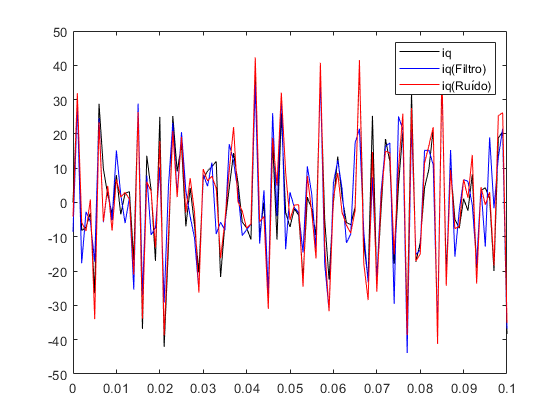


figure(2)
plot(tempo,y(:,2),'k-',tempo,yestimativa(2,:),'b-',tempo,yruido(:,2),'r-')
legend('iq','iq(Filtro)','iq(Ruído)')

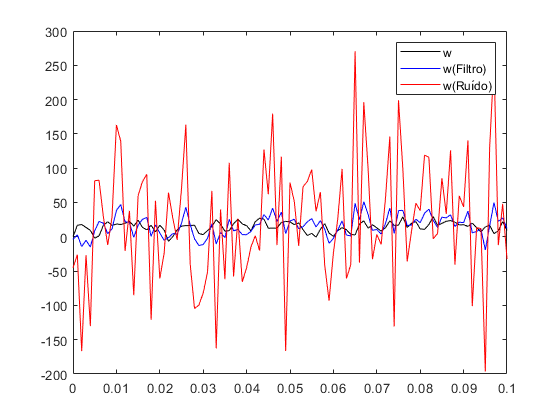


figure(3)
plot(tempo,y(:,3),'k-',tempo,yestimativa(3,:),'b-',tempo,yruido(:,3),'r-')
legend('w','w(Filtro)','w(Ruído)')

## Simulação e Análise

nExp = 100; % Número de experimentos 
atrito = b;
var = 0.25; % Percentual de variação
resultado = zeros(nExp, 1); 

% Inicializando o modelo
mdl = 'TRABALHO_SIMULINK'; 
open_system(mdl);

for iExp = 1:nExp
    
    coefAtrito = atrito * (1 + var*randn); % Ajuste de b com variação randomica
    set_param('TRABALHO_SIMULINK/PMSM6', 'b', num2str(coefAtrito)); % Aplica b no modelo d simulink
% set_param('TrabalhoP2Simulink/v','Seed',num2str(seedV));
    % Executa a simulação e armazena o último valor do sinal
    saida = sim(mdl);
    dadosW = saida.yout{5}.Values.Data; 
    dadosIq = saida.yout{6}.Values.Data;
    dadosId = saida.yout{7}.Values.Data; 
    resultadoW(iExp) = dadosW(end);
    overshoot = max(dadosW) - resultadoW(iExp); % Calculo do overshoot
    resultado(iExp) = overshoot;
    resultadoIq(iExp) = dadosIq(end);
    resultadoId(iExp) = dadosId(end);
end

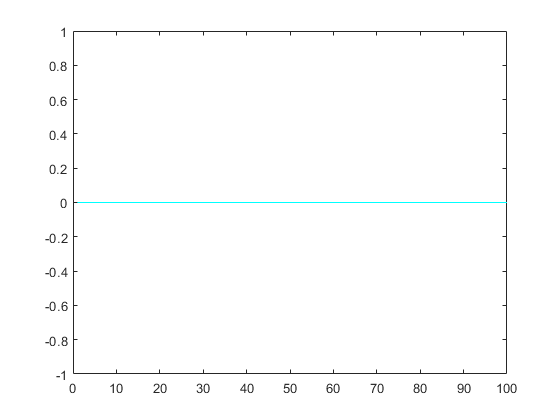


% Visualizar resultados
figure;
plot(resultado,'cyan');

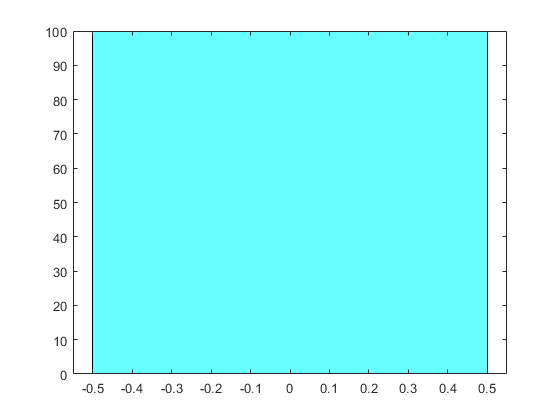

histogram(resultado,'FaceColor','c');

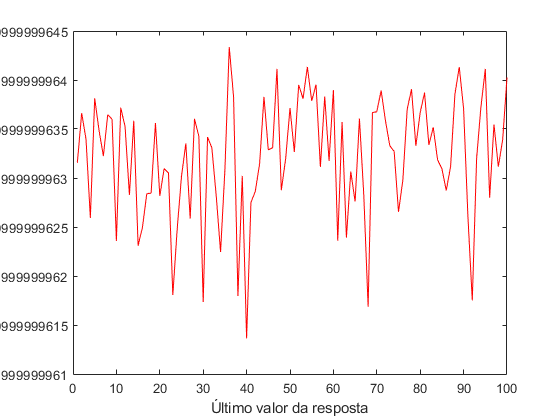

% grid on;

figure(1);
plot(resultadoW, 'red');
xlabel('Último valor da resposta');
ylabel('Velocidade (rad/s)');

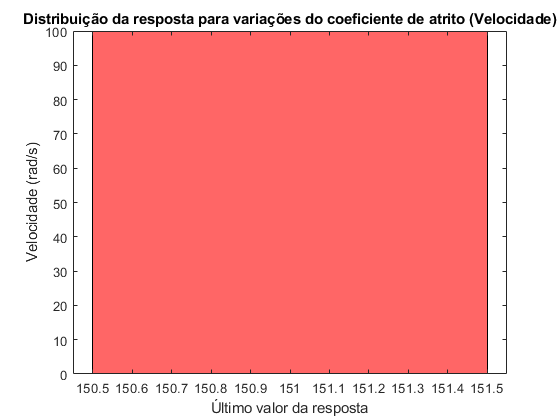

histogram(resultadoW,'FaceColor','r');
xlabel('Último valor da resposta');
ylabel('Velocidade (rad/s)');
title('Distribuição da resposta para variações do coeficiente de atrito (Velocidade)');

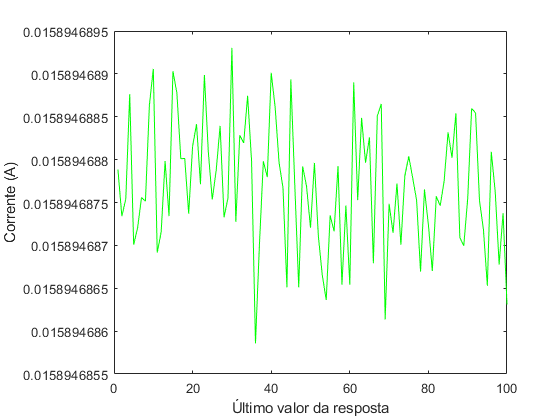


figure(2);
plot(resultadoIq,'green');
xlabel('Último valor da resposta');
ylabel('Corrente (A)');

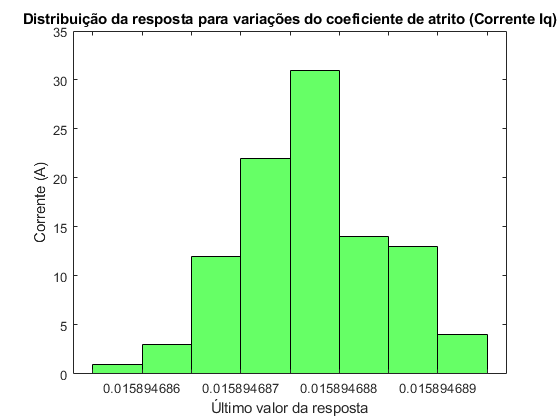

histogram(resultadoIq,'FaceColor','g');
xlabel('Último valor da resposta');
ylabel('Corrente (A)');
title('Distribuição da resposta para variações do coeficiente de atrito (Corrente Iq)');

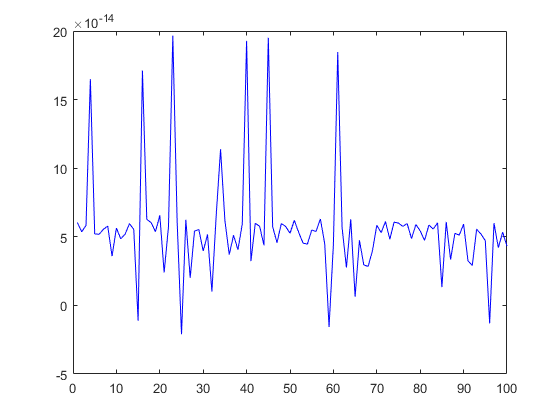


figure(3);
plot(resultadoId,'blue');

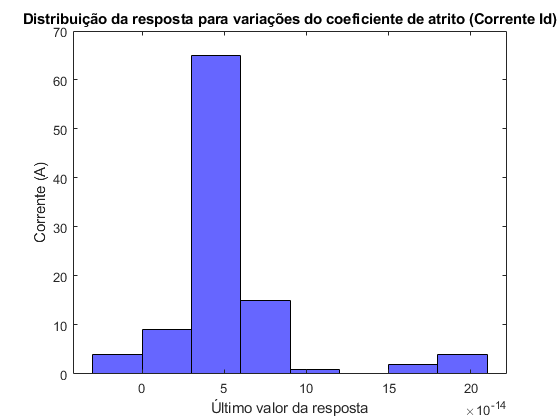

histogram(resultadoId,'FaceColor','b');
xlabel('Último valor da resposta');
ylabel('Corrente (A)');
title('Distribuição da resposta para variações do coeficiente de atrito (Corrente Id)');


J = @ (xJ) exp(-2e+07*(xJ.^2));
% areaHist = trapz(-1000000:10:1000000,J(-1000000:10:1000000));
xJ=linspace(-5e-3,5e-3,10000);
J2 = @ (x) exp(-2e+07*((x-0.9).^2))/trapz(xJ,J(xJ));
xProb = linspace(0.901,5e-3+0.901,1000); 
Resultado = trapz(xProb,J2(xProb))*100

Resultado = 1.2742e-08